# Ecuaciones lineales de primer orden  

# Problemas de valor inicial

Use separation of variables to find solutions of the IVP given by y(0) = 1 and the following differential equations:

(a)$\frac{\mathrm{d}}{\mathrm{d}t}y=t$    (b) $\frac{\mathrm{d}}{\mathrm{d}t}y=t^2 y$    (c) $\frac{\mathrm{d}}{\mathrm{d}t}y=2\left(t+1\right)y\;$

% t en [0,2]
f1=@(t,y) t;
f2=@(t,y) t^2*y;
f3=@(t,y) 2*(t+1)*y;
t0=0;
tf=2;
y0=1;
h=0.1;
[t,y1]=odeEuler2(f1,t0,y0,tf,h);
[t,y2]=midPoint(f1,t0,y0,tf,h);
[t,y3]=odeEuler(f2,t0,y0,tf,h);
[t,y4]=midPoint(f2,t0,y0,tf,h);
[t,y5]=odeEuler(f3,t0,y0,tf,h);
[t,y6]=midPoint(f3,t0,y0,tf,h);
plot(t,y1,t,y2)
plot(t,y3,t,y4)
plot(t,y5,t,y6)
legend


$$y^{\prime } =y\left(1-y\right)$$
      
$$y\left(0\right)=1/2$$


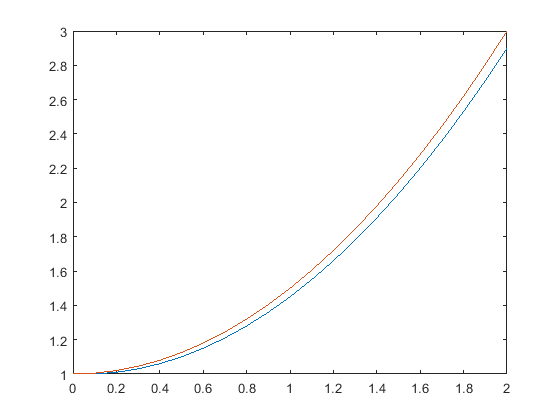

% t en [0,6]
t0=0;

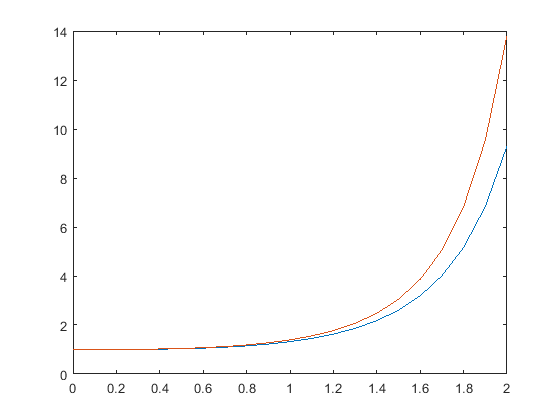

tf=6;

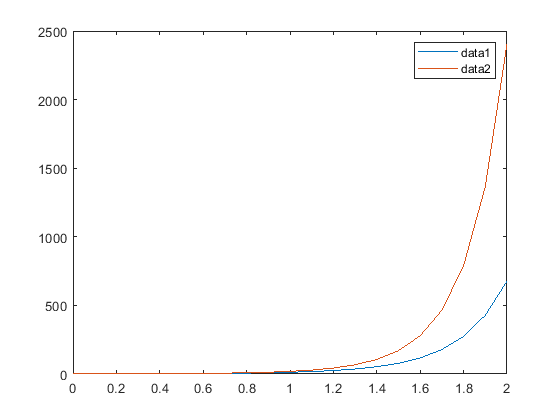

y0=1/2;
h=0.8

f=@(t,y) y*(1-y);
[t,y1]=odeEuler(f,t0,y0,tf,h);
[t,y2]=midPoint(f,t0,y0,tf,h);
[t,y3] = odeHuen(f,t0,h,tf,y0);
[t,y4] = RK4(f,t0,h,tf,y0);
plot(t,y1,t,y2,t,y3,t,y4)


h = 0.8000


$$y^{\prime } =k{\left(a_0 -y\right)}^2 \left(b_0 -y/2\right)$$
     
$$y\left(0\right)=0$$


$k=0\ldotp 00713$; $a_0 =4$; $b_0 =1$

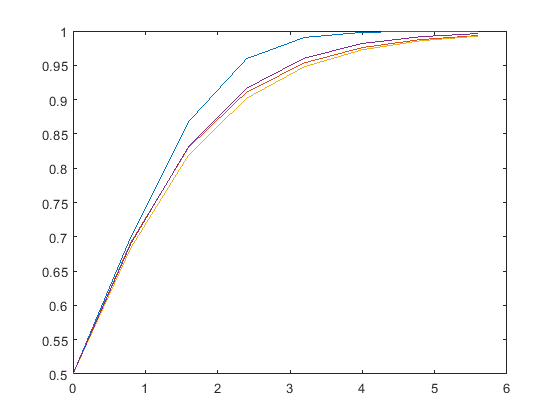

% t en [0,400]
t0=0;

tf=400;
k=0.00713;
a0=4;
b0=1;
y0=0;
f=@(t,y) k*((a0-y)^2)*(b0-y/2);
h=5
[t,y1]=odeEuler(f,t0,y0,tf,h);
[t,y2]=midPoint(f,t0,y0,tf,h);
[t,y3] = odeHuen(f,t0,h,tf,y0);
[t,y4] = RK4(f,t0,h,tf,y0);
plot(t,y1,t,y2,t,y3,t,y4)
axis([0 300 0 2])


Resuelve el siguiente problema de valor inicial en el intervalo de $t=0$ a $t=2$


$$y^{\prime } =yt^2 -1\ldotp 1y$$
      
$$y\left(0\right)=1$$


% Solucion analitica
syms y(t) 
eqn = diff(y,t) == y*t^2 - 1.1*y;

h = 5

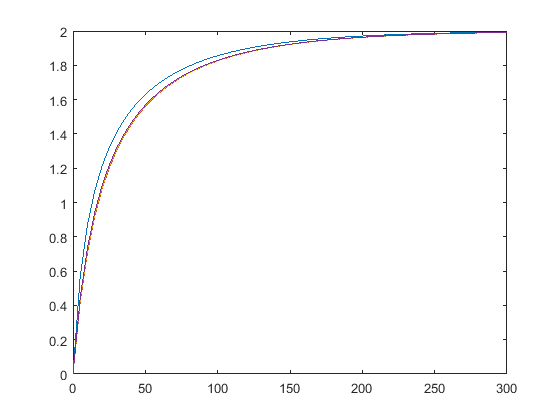

yG = dsolve(eqn)
cond = y(0) == 1;
yP = dsolve(eqn,cond)
fplot(yP, [0 2]);
hold off;
%solución con método numérico

f=@(t,y) y*t^2-1.1*y;
t0=0;
tf=2;
y0=1;
h=0.5
[t,y1]=odeEuler(f,t0,y0,tf,h);
[t,y2]=midPoint(f,t0,y0,tf,h);
[t,y3] = odeHuen(f,t0,h,tf,y0);

$$yG = C_{1}\,{\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

[t,y4] = RK4(f,t0,h,tf,y0);
plot(t,y1,t,y2,t,y3,t,y4)

$$yP = {\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

¿En cuántos minutos se vaciará un tanque que inicialmente tiene 3 metros de agua?

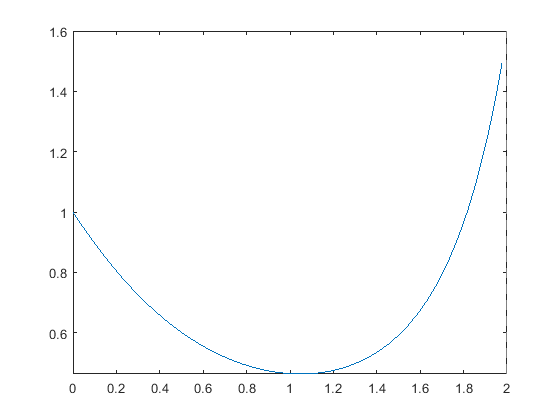

f=@(y,t) 1/(-k*sqrt(y));
y0=0;

t0=0;
tf=3;
[t,y4] = RK4(f,t0,h,tf,y0)

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. Simula la población mundial entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

¿Cuántos millones de personas habrá en 2022?

%

More examples

% y(0) = 1; 0 <=t<= 10;
% f         Exact solution

h = 0.5000

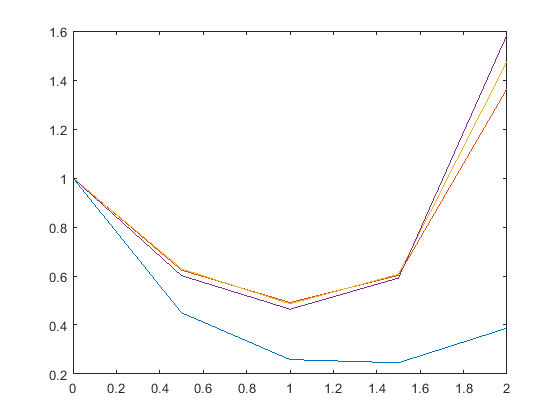

% 0         1
% t         1+t^2/2
% y         exp(t)
% -y        exp(-t)
% 2*y-y^2   2/(1+exp(-2*t))

function [t,y]=odeEuler(f,t0,y0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(size(t));
    y(1)=y0;
    for i=2:n
        phi=f(t(i-1),y(i-1));
        y(i)=y(i-1)+phi*h;
    end

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


y4 =      0   Inf   Inf   Inf   Inf   Inf   Inf


    
end
function [t,y]=odeEuler2(f,t0,y0,tf,h)
    t=t0:h:tf;
    n=length(y0);
    m=length(t);
    y=zeros(n,m);
    y(:,1)=y0;
    for i=2:m
        phi=f(t(i-1),y(:,i-1));
        y(:,i)=y(:,i-1)+phi*h;
    end
    
end
function [t,y]=midPoint(f,t0,y0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(size(t));
    y(1)=y0;
    for i=1:n-1
        ymp=y(i)+f(t(i),y(i))*h/2;
        phi=f(t(i)+h/2,ymp);
        y(i+1)=y(i)+phi*h;
    end
end

function [x,y] = odeHuen(f,x0,h,xf,y0)

    % Initialize the output solution arrays.
    x = x0:h:xf;
    m = length(y0);
    n=length(x);
    y = zeros(m,n);
    y(:,1) = y0;
    
    
    % Compute x an y by integrating the ODE system using Huen's method. 
    tol=eps;
    Max=100;
    cond=true;
    i=1;
    
    while cond
        k1=f(x(i),y(:,i));
        k2=f(x(i)+h,y(:,i)+k1*h);
        the=(k1+k2)/2;
        y(:,i+1)=y(:,i)+the*h;
        i=i+1;
        cond= norm((y(:,i)-y(:,i-1))/y(:,i),inf)>tol && i<n;
    end


end
function [t,y] = RK4(f,t0,h,tf,y0)

    % Initialize the output solution arrays.
    t=t0:h:tf;
    n=length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    
    % Compute x an y by integrating the ODE system using Huen's method. 
    cond=true;
    i=1;
    
    while cond
        k1=f(t(i),y(:,i));
        k2=f(t(i)+h/2,y(:,i)+(k1/2)*h);
        k3=f(t(i)+h/2,y(:,i)+(k2/2)*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        the=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+the*h;
        i=i+1;
        cond=i<n;
    end


end